clc;
clear;
close all;
tic

numTx = 4; % number of tx antennas
numRx = 4; % number of rx antennas

M = 16; % modulation order (16-QAM)
num_symbols = numTx*numRx*10^3; % number of transmitted symbols
symbols = randi([0 M-1], 1, num_symbols); % generate random symbols

deltas = ones(1,numTx);

points = 40; % points to plot
snr=linspace(0,points-1,points); 
ser=zeros(1,length(snr));

xmod = qammod(symbols, M); % modulates input signal x by using QAM with the specified modulation order M
% scatterplot(xmod)
xmod=reshape(xmod,numTx,num_symbols/numTx);
xmod=kron(xmod,deltas); % Kronecker tensor product

% Rayleigh channel fading
h = zeros(numTx*numRx, num_symbols/numRx);
for l=1:(numTx*numRx)
    h(l,:)=(1/sqrt(2))*(randn(1,num_symbols/numRx)+1i*randn(1,num_symbols/numRx));
end

H = reshape(h, numTx, num_symbols);
tmp = sum(H.*xmod,1); % sum on the columns
y = reshape(tmp, numRx, num_symbols/numRx);
H=reshape(h,numTx,numRx,num_symbols/numRx);

for k=1:length(snr)
    N1 = 1 / sqrt(2) * (randn(1,num_symbols)+1i*randn(1,num_symbols));
    N1 = reshape(N1, numRx, num_symbols/numRx);
    
    ynoisy=y+10^(-(snr(k)-10*log10(M))/20)*N1;
    ynoisy=reshape(ynoisy,numRx,1,num_symbols/numRx);
    
    B=[];
    rcvd=[];
    
    for l=1:num_symbols/numRx
        
        Heq=transpose(H(:,:,l));
        B=pinv(Heq);
        rcvd=[rcvd,B*ynoisy(:,:,l)];
    end
    
    final_y=qamdemod(reshape(rcvd,1,num_symbols),M);
%     [num, ser(k)]=symerr(symbols(end-(num_symbols*numTx/numRx)+1:end),final_y);
    [num, ty]=symerr(symbols,final_y);
    ser(k)=ty/log2(M);
end

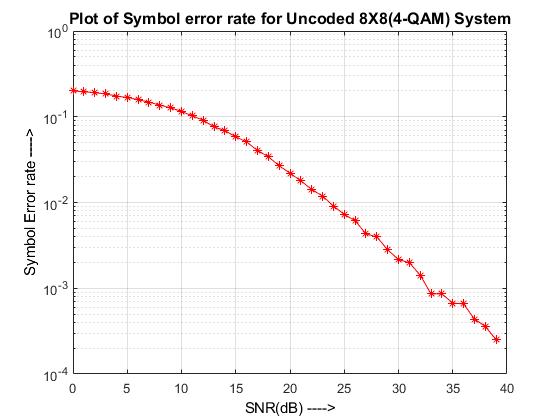

semilogy(snr,ser,'r-*');
grid on;hold on;
title('Plot of Symbol error rate for Uncoded 8X8(4-QAM) System','FontSize',12);
% legend('sim (nTx=8, nRx=8, Uncoded(4-QAM)) Using ZF','location','southwest');
xlabel('SNR(dB) ---->','Color','k','FontSize',11);
ylabel('Symbol Error rate ---->','Color','k','FontSize',11);

toc

Elapsed time is 5.954020 seconds.
